# КУМС. ЛР 4. 

Денис Кирбаба R3438

#### 1. Параметры по вариантам

% ob.R = 10 + unifrnd(-1,1);  % сопротивление обмоток двигателя
% ob.L = 0.02 + unifrnd(-0.01,0.01);  % индуктивность обмоток двигателя
% ob.J = 100 + unifrnd(-10,10);  % момент инерции
% ob.Ce = 2;  % константа противо-ЭДС
% ob.Cm = ob.Ce;  % константа по моменту
% ob.kdw = 180/pi;  % коэффициент передачи датчика скорости (пересчет из радиан в градусы)
% save('data.mat','ob')

load("data.mat")

#### 2. Моделирование Д-регулятора

**a) Работа цифрового Д-регулятора**

an.Kd = 3;
dsc.Kd = an.Kd;

Tmdl = 1;
To = 0.05;

Входной сигнал - константа

k = 1;

warning off
SimNew = sim('lab4p2a.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.y(:,1);
an.y = SimNew.y(:,2);
dsc.y = SimNew.y(:,3);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,an.y,'LineWidth',2)
hold on
grid on
plot(t,dsc.y,'LineWidth',2)
xlabel('\it t\rm,\it s')
ylabel('\it u\rm(\itt\rm)')
legend('аналоговый Д-регулятор','дискретный Д-регулятор','Location','best')
ylim([0 100])

Синий график идет до бесконечности в случае, если мы бы смогли реализовать идеальное дифференцирующее звено. В данном случае мы реализовывает его в виде передаточной функции: s / (0.0001*s + 1). При стремлении коэффициента в знаменателе у переменной s к 0, график будет иметь всё большее значение в начале переходного процесса.

Красный график у нас немного отличается. 

Разница между аналоговым и цифровым Д-регулятором в том, что цифровой регулятор имеет кусочно-постоянный сигнал управления, с шириной равной периоду дискретизации, а аналоговый в идеальном случае является функцией Хевисайда в момент t -> +0. А одинаковое у обоих сигналов - энергия ими переносимая (площадь по графиками), она равна коэффициенту регулятором an.Kd = dsc.Kd = 3. 

Поэтому с точки зрения энергии воздействия оба регулятора аналогичны, с точки зрения формы сигнала - существенно рзаличны.

Входной сигнал - линейно возрастающий

k = 2;

warning off
SimNew = sim('lab4p2a.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.y(:,1);
an.y = SimNew.y(:,2);
dsc.y = SimNew.y(:,3);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,an.y,'LineWidth',2)
hold on
grid on
plot(t,dsc.y,'LineWidth',2)
xlabel('\it t\rm,\it s')
ylabel('\it u\rm(\itt\rm)')
legend('аналоговый Д-регулятор','дискретный Д-регулятор','Location','best')

В случай линейно-возрастающего входа оба графика приходят к значению 3, но аналоговый приходит моментально (с учетом 0.0001 -> 0), а аналоговый отстает на 1 такт дискретизации. 

Для компенсации отставания дискретного регулятора нам опять же придется вводить в аналоговой системе эквивалентное запаздывание, чтобы учесть переход от аналоговой к цифровой системы.

**б) Цифровой ПД-регулятор – апериодическое звено первого порядка**

Суть компенсации постоянной времени T, заключается в том, чтобы составляющие ПД-регулятора в числителе давали Ts+1, чтобы это сократилось со знаменателем апериодического звена и будет получаться безинерционное звено (в идеальном случае).

T = 0.5;
Tmdl = 1;
To = 0.05;

an.Kp = 1;
an.Kd = T;

dsc.Kp1 = an.Kp;
dsc.Kd1 = an.Kd;

dsc.Kp2 = an.Kp;
dsc.Kd2 = 1/(exp(To/T)-1);

warning off
SimNew = sim('lab4p2b.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.y(:,1);
an.y = SimNew.y(:,2);
dsc1.y = SimNew.y(:,3);
dsc2.y = SimNew.y(:,4);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,an.y,'LineWidth',2)
hold on
grid on
plot(t,dsc1.y,'LineWidth',2)
plot(t,dsc2.y,'LineWidth',2)
xlabel('\it t\rm,\it s')
ylabel('\it u\rm(\itt\rm)')
legend('аналоговый ПД-регулятор','дискретный ПД-регулятор (1 вариант расчета)' ...
    ,'дискретный ПД-регулятор (2 вариант расчета)','Location','best')

Усиление сигнала

Kg = 5;

T = 0.5;
Tmdl = 1;
To = 0.05;

an.Kp = Kg*1;
an.Kd = Kg*T;

dsc.Kp1 = an.Kp;
dsc.Kd1 = an.Kd;

dsc.Kp2 = an.Kp;
dsc.Kd2 = Kg/(exp(To/T)-1);

warning off
SimNew = sim('lab4p2b.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.y(:,1);
an.y = SimNew.y(:,2);
dsc1.y = SimNew.y(:,3);
dsc2.y = SimNew.y(:,4);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,an.y,'LineWidth',2)
hold on
grid on
plot(t,dsc1.y,'LineWidth',2)
plot(t,dsc2.y,'LineWidth',2)
xlabel('\it t\rm,\it s')
ylabel('\it u\rm(\itt\rm)')
legend('аналоговый ПД-регулятор','дискретный ПД-регулятор (1 вариант расчета)' ...
    ,'дискретный ПД-регулятор (2 вариант расчета)','Location','best')

**с) Непрерывная модель цифрового ПД-регулятора, учитывающая неполную компенсацию цифровым регулятором постоянной объекта             **

Произведем поиск эквивалентного звена запаздывания

To = 0.05;
T = 5*To;

Kg = 5;

Tmdl = 1;

an.Kp = Kg*1;
an.Kd = Kg*T;

dsc.Kp2 = an.Kp;
dsc.Kd2 = Kg/(exp(To/T)-1);

clear Tur f
for i = 1:10
    an.Tur = i/10*To;  % диапазон изменения Tz
    Tur(i) = an.Tur;
    warning off
    SimNew = sim('lab4p2c.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.y(:,1);
    an.y = SimNew.y(:,2);
    dsc.y = SimNew.y(:,3); 
    f(i) = trapz(t,abs(an.y-dsc.y));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Теперь строим график и ищем минимум функционала

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tur/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{ur}/T_o')
ylabel('\it f')
T = 0.5;
Tmdl = 1;
To = 0.05;

an.Tur = 0.5*To;
an.Kp = Kg*1;
an.Kd = Kg*T;

dsc.Kp2 = an.Kp;
dsc.Kd2 = Kg/(exp(To/T)-1);

warning off
SimNew = sim('lab4p2c.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.y(:,1);
an.y = SimNew.y(:,2);
dsc.y = SimNew.y(:,3);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,an.y,'LineWidth',2)
hold on
grid on
plot(t,dsc.y,'LineWidth',2)
xlabel('\it t\rm,\it s')
ylabel('\it u\rm(\itt\rm)')
legend('аналоговый ПД-регулятор с задержкой','дискретный ПД-регулятор (2 вариант расчета)','Location','best')

#### 3. **Синтез системы с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового ПД-регулятора для случая вычислительной задержки ε = *****Тo***

**a) Синтез регулятора**

Tt = 0.005;

crl.Kpa = ob.L/Tt;
crl.Kia = ob.R/Tt;

kdw = 180/pi;
Tmdl = 0.1;

syms Tu s Tt Ce J

Коэффициент передачи датчика скорости

syms kdw
Wcrl = 1/(Tt*s+1);
Wob2 = Ce*kdw/(J*s);

Передаточная функция разомкнутой системы, настроенной на технический оптимум

Wol = 1/(3*Tu*s*(Tu*s+1));
Wreg = Wol/(Wcrl*Wob2);

disp(simplify(collect(Wreg,s)))

$$\frac{J\,\left(\mathrm{Tt}\,s+1\right)}{3\,\mathrm{Ce}\,\mathrm{Tu}\,\mathrm{kdw}\,\left(\mathrm{Tu}\,s+1\right)}$$

**б) Моделирование системы настроенной на технический оптимум**

crl.Tt = 0.005;
To = 0.1*crl.Tt;

crl.Kpa = ob.L/crl.Tt;
crl.Kia = ob.R/crl.Tt;

kdw = 180/pi;
Tmdl = 0.0125;

spl.Tur = 0.5*To;
spl.Tu = spl.Tur;
spl.Kg = ob.J/(3*ob.Ce*spl.Tu*kdw);

Аналоговый ПД-регулятор

spl.Kpa = spl.Kg*1;
spl.Kda = spl.Kg*crl.Tt;

Дискретный ПД-регулятор

spl.Kp2dg = spl.Kpa;
spl.Kd2dg = spl.Kg/(exp(To/crl.Tt)-1);

warning off
SimNew = sim('lab4p3a.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab4p3a/Subsystem/crl.Kp
lab4p3a/Subsystem/Sum
lab4p3a/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab4p3a/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab4p3a/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab4p3a/Subsystem1/crl.Kp
lab4p3a/Subsy

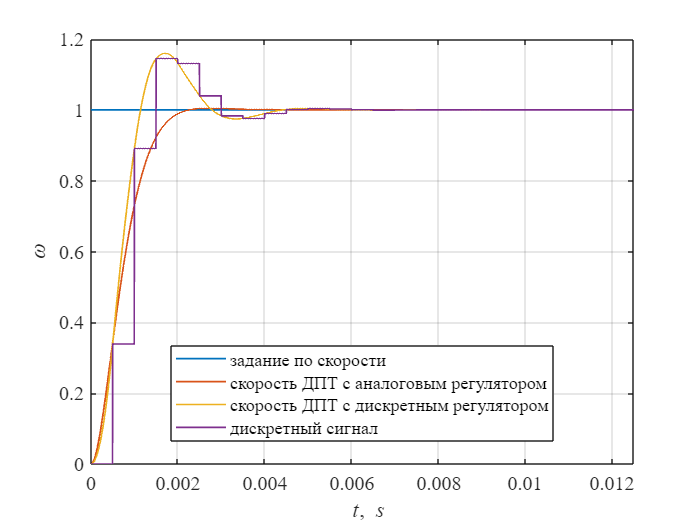

warning on

t = SimNew.w(:,1);
wref=SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 4.3*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 9.8*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 16.0%


**в) Аппроксимация апериодическим звеном**

for i = 1:10
    spl.Tz = i/10*To;  % диапазон изменения Tz
    Tzap(i) = spl.Tz;
    warning off
    SimNew = sim('lab4p3b.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.w(:,1);
    wa = SimNew.w(:,3);
    wd = SimNew.w(:,4);
    f(i) = trapz(t,abs(wd-wa));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Found algebraic loop containing: 
lab4p3b/Subsystem/crl.Kp
lab4p3b/Subsystem/Sum
lab4p3b/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab4p3b/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab4p3b/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab4p3b/Subsystem1/crl.Kp
lab4p3b/Subsy

Теперь строим график и ищем минимум функционала

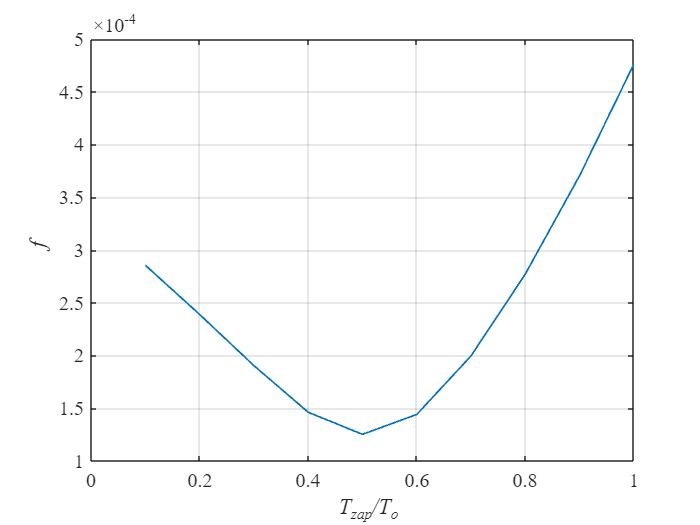

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

**г) Синтез цифрового ПД-регулятора методом переоборудования**

**To = 0.1 Tt**

crl.Tt = 0.005;
To = 0.1*crl.Tt;

crl.Kpa = ob.L/crl.Tt;
crl.Kia = ob.R/crl.Tt;

kdw = 180/pi;
Tmdl = 0.0125;

spl.Tur = 0.5*To;
spl.Tz = 0.5*To;
spl.Tu = spl.Tur + spl.Tz;
spl.Kg = ob.J/(3*ob.Ce*spl.Tu*kdw);

Аналоговый ПД-регулятор

spl.Kpa = spl.Kg*1;
spl.Kda = spl.Kg*crl.Tt;

Дискретный ПД-регулятор

spl.Kp2dg = spl.Kpa;
spl.Kd2dg = spl.Kg/(exp(To/crl.Tt)-1);

warning off
SimNew = sim('lab4p3b.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab4p3b/Subsystem/crl.Kp
lab4p3b/Subsystem/Sum
lab4p3b/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab4p3b/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab4p3b/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab4p3b/Subsystem1/crl.Kp
lab4p3b/Subsy

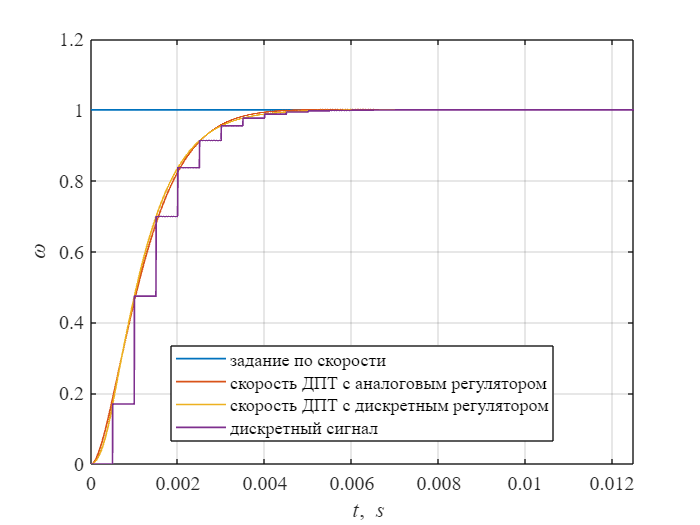

warning on

t = SimNew.w(:,1);
wref=SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 5.8*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 5.8*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 0.0%


**To = 0.5 Tt**

crl.Tt = 0.005;
To = 0.5*crl.Tt;

crl.Kpa = ob.L/crl.Tt;
crl.Kia = ob.R/crl.Tt;

kdw = 180/pi;
Tmdl = 0.05;

spl.Tur = 0.5*To;
spl.Tz = 0.5*To;
spl.Tu = spl.Tur + spl.Tz;
spl.Kg = ob.J/(3*ob.Ce*spl.Tu*kdw);

Аналоговый ПД-регулятор

spl.Kpa = spl.Kg*1;
spl.Kda = spl.Kg*crl.Tt;

Дискретный ПД-регулятор

spl.Kp2dg = spl.Kpa;
spl.Kd2dg = spl.Kg/(exp(To/crl.Tt)-1);

warning off
SimNew = sim('lab4p3b.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab4p3b/Subsystem/crl.Kp
lab4p3b/Subsystem/Sum
lab4p3b/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab4p3b/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab4p3b/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab4p3b/Subsystem1/crl.Kp
lab4p3b/Subsy

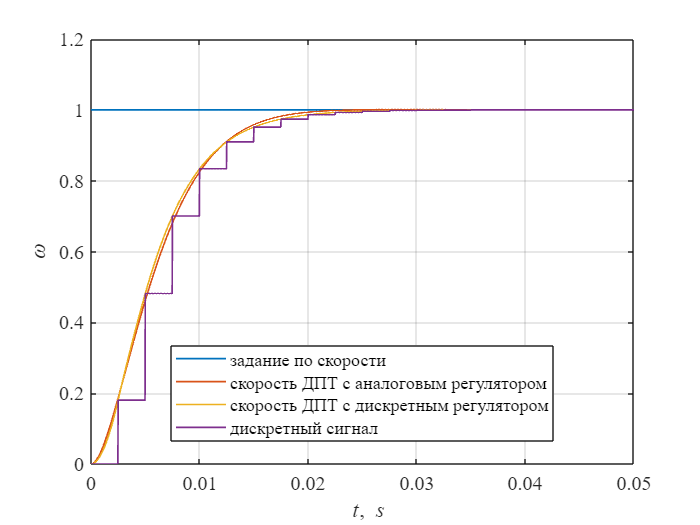

warning on

t = SimNew.w(:,1);
wref=SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 6.0*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 6.0*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 0.0%


**4. Синтез системы с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового ПД-регулятора для случая вычислительной задержки ε = *****Т0***

** а) Аппроксимация апериодическим звеном**

for i = 1:20
    spl.Tz = i/10*To;  % диапазон изменения Tz
    Tzap(i) = spl.Tz;
    warning off
    SimNew = sim('lab4p4a.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.w(:,1);
    wa = SimNew.w(:,3);
    wd = SimNew.w(:,4);
    f(i) = trapz(t,abs(wd-wa));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Found algebraic loop containing: 
lab4p4a/Subsystem/crl.Kp
lab4p4a/Subsystem/Sum
lab4p4a/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab4p4a/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab4p4a/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab4p4a/Subsystem1/crl.Kp
lab4p4a/Subsy

Теперь строим график и ищем минимум функционала

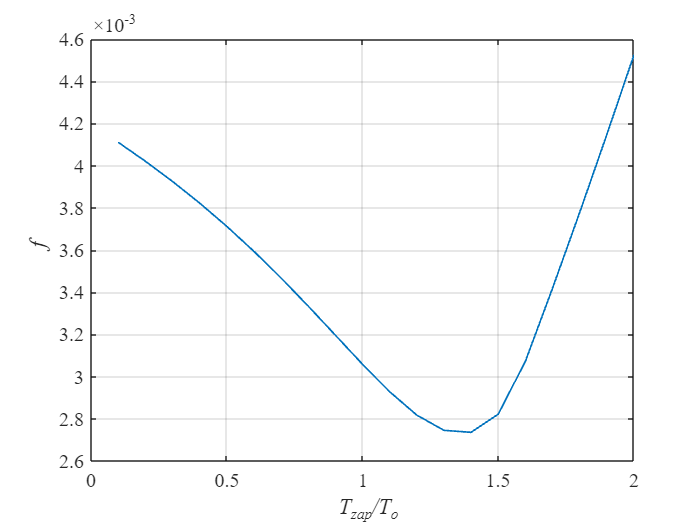

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

**б) Синтез цифрового ПД-регулятора методом переоборудования**

**To = 0.1 Tt**

crl.Tt = 0.005;
To = 0.1*crl.Tt;

crl.Kpa = ob.L/crl.Tt;
crl.Kia = ob.R/crl.Tt;

kdw = 180/pi;
Tmdl = 0.0125;

spl.Tur = 0.5*To;
spl.Tz = 1.4*To;
spl.Tu = spl.Tur + spl.Tz;
spl.Kg = ob.J/(3*ob.Ce*spl.Tu*kdw);

Аналоговый ПД-регулятор

spl.Kpa = spl.Kg*1;
spl.Kda = spl.Kg*crl.Tt;

Дискретный ПД-регулятор

spl.Kp2dg = spl.Kpa;
spl.Kd2dg = spl.Kg/(exp(To/crl.Tt)-1);

warning off
SimNew = sim('lab4p4a.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab4p4a/Subsystem/crl.Kp
lab4p4a/Subsystem/Sum
lab4p4a/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab4p4a/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab4p4a/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab4p4a/Subsystem1/crl.Kp
lab4p4a/Subsy

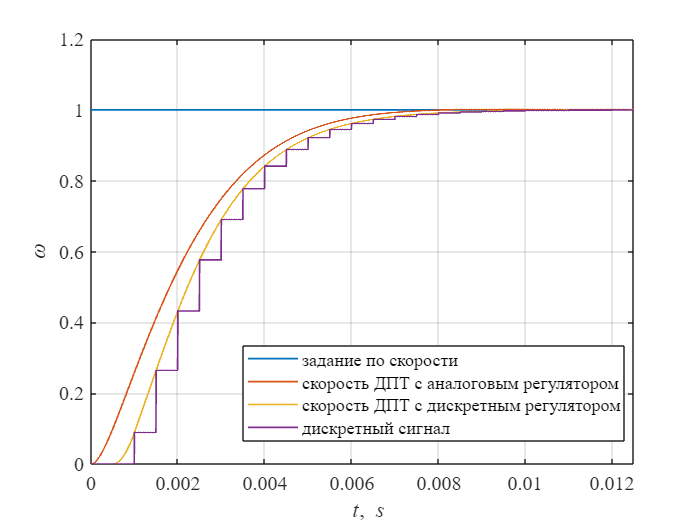

warning on

t = SimNew.w(:,1);
wref=SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 5.9*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 5.9*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 0.0%


**To = 0.5 Tt**

crl.Tt = 0.005;
To = 0.5*crl.Tt;

crl.Kpa = ob.L/crl.Tt;
crl.Kia = ob.R/crl.Tt;

kdw = 180/pi;
Tmdl = 0.05;

spl.Tur = 0.5*To;
spl.Tz = 1.4*To;
spl.Tu = spl.Tur + spl.Tz;
spl.Kg = ob.J/(3*ob.Ce*spl.Tu*kdw);

Аналоговый ПД-регулятор

spl.Kpa = spl.Kg*1;
spl.Kda = spl.Kg*crl.Tt;

Дискретный ПД-регулятор

spl.Kp2dg = spl.Kpa;
spl.Kd2dg = spl.Kg/(exp(To/crl.Tt)-1);

warning off
SimNew = sim('lab4p4a.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab4p4a/Subsystem/crl.Kp
lab4p4a/Subsystem/Sum
lab4p4a/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab4p4a/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab4p4a/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab4p4a/Subsystem1/crl.Kp
lab4p4a/Subsy

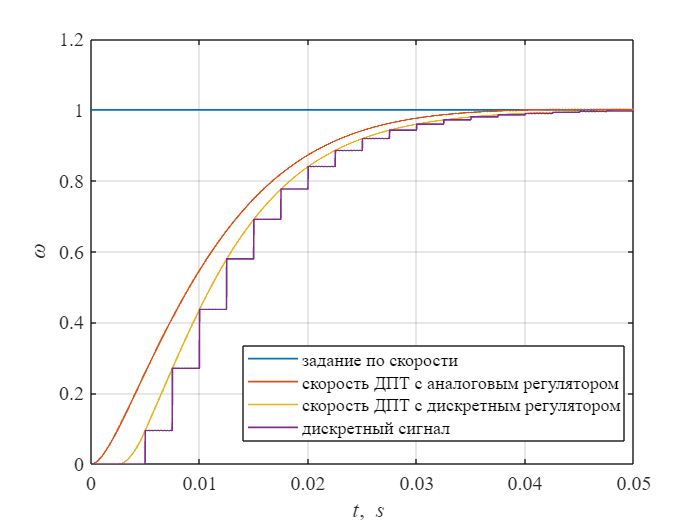

warning on

t = SimNew.w(:,1);
wref=SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 5.9*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 5.9*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 0.0%
